syms q1 q2 q3 x h % DOF
syms q1dot q2dot q3dot hdot xdot%
q = [q1; q2; q3; x; h];
qdot = [q1dot; q2dot; q3dot; xdot; hdot];

% DOF wrt t
syms qt1(t) qt2(t) qt3(t) ht(t) xt(t)
qt(t) = [qt1; qt2; qt3; xt; ht];

%Link Lengths
L1 = 1;
L2 = 1;
L3 = 1;

%Masses
density = 1;
Area = 1;
M1 = L1*density*Area;
M2 = L2*density*Area;
M3 = L3*density*Area;

M = [M1, M2, M3, 0]

M =      1     1     1     0


%Theta
Th1 = q1;
Th2 = q1 + q2;
Th3 = q1 + q2 + q3;

%Relative End Posistions
OE1 = L1*[cos(Th1) sin(Th1)]

$$OE1 = \left(\begin{array}{cc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) \end{array}\right)$$

E1E2 = L2*[cos(Th2) sin(Th2)]

$$E1E2 = \left(\begin{array}{cc} \cos\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{2}\right) \end{array}\right)$$

E2E3 = L3*[cos(Th3) sin(Th3)]

$$E2E3 = \left(\begin{array}{cc} \cos\left(q_{1}+q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$


O = [0 0];
E1 = O + OE1;
E2 = E1 + E1E2;
E3 = E2 + E2E3;

C1 = O + .5*OE1;
C2 = E1 + .5*E1E2;
C3 = E2 + .5*E2E3;
C = [C1 C2 C3]

$$C = \left(\begin{array}{cccccc} \frac{\cos\left(q_{1}\right)}{2} & \frac{\sin\left(q_{1}\right)}{2} & \frac{\cos\left(q_{1}+q_{2}\right)}{2}+\cos\left(q_{1}\right) & \frac{\sin\left(q_{1}+q_{2}\right)}{2}+\sin\left(q_{1}\right) & \frac{\cos\left(q_{1}+q_{2}+q_{3}\right)}{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \frac{\sin\left(q_{1}+q_{2}+q_{3}\right)}{2}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right) \end{array}\right)$$


%%

qt2(t) = -1/2.5*exp(-(t-5)^2/2)-pi/2

$$qt2(t) = -\frac{\pi }{2}-\frac{2\,{\mathrm{e}}^{-\frac{{\left(t-5\right)}^{2}}{2}}}{5}$$

qt3(t) = 1/2.5*exp(-(t-5)^2/2)+pi/2

$$qt3(t) = \frac{\pi }{2}+\frac{2\,{\mathrm{e}}^{-\frac{{\left(t-5\right)}^{2}}{2}}}{5}$$

CMstart =subs(COM([C1;C2;C3],M), [q2,q3], [qt2,qt3]);
CMstart = CMstart(1) == 0

$$CMstart = \frac{\cos\left(\frac{\pi }{2}-q_{1}+\frac{2\,{\mathrm{e}}^{-\frac{{\left(t-5\right)}^{2}}{2}}}{5}\right)}{2}+\cos\left(q_{1}\right)=0$$

assume(0<q1<pi)
assume(0<t)
q1start = solve(CMstart,q1,'ReturnConditions',true,'Real',true)

q1start = struct with fields:
            q1: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]


q1start.q1

$$ans = \begin{array}{l} \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\sigma_{3}+\sigma_{1}}{\sigma_{2}-2}\right)\\ -2\,\mathrm{atan}\left(\frac{\sigma_{3}-\sigma_{1}}{\sigma_{2}-2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\sigma_{2}}^{2}-4\,\sigma_{2}+{\sigma_{3}}^{2}+4}\\ \sigma_{2}=\sin\left(\frac{2\,{\mathrm{e}}^{5\,t}\,{\mathrm{e}}^{-\frac{25}{2}}}{5\,\sqrt{{\mathrm{e}}^{t^{2}}}}\right)\\ \sigma_{3}=\cos\left(\frac{2\,{\mathrm{e}}^{5\,t}\,{\mathrm{e}}^{-\frac{25}{2}}}{5\,\sqrt{{\mathrm{e}}^{t^{2}}}}\right) \end{array}$$

q1start.conditions

$$ans = \begin{array}{l} \left(\begin{array}{c} \left(\sigma_{2}<0\wedge \sigma_{1}<0\right)\vee \left(\sigma_{2}<0\wedge 0\leq \sigma_{1}\right)\\ \left(\sigma_{2}<0\wedge \sigma_{1}<0\right)\vee \left(0\leq \sigma_{2}\wedge \sigma_{1}<0\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{atan}\left(\frac{\sigma_{4}-\sqrt{{\sigma_{3}}^{2}-4\,\sigma_{3}+{\sigma_{4}}^{2}+4}}{\sigma_{3}-2}\right)\\ \sigma_{2}=\mathrm{atan}\left(\frac{\sigma_{4}+\sqrt{{\sigma_{3}}^{2}-4\,\sigma_{3}+{\sigma_{4}}^{2}+4}}{\sigma_{3}-2}\right)\\ \sigma_{3}=\sin\left(\frac{2\,{\mathrm{e}}^{5\,t}\,{\mathrm{e}}^{-\frac{25}{2}}}{5\,\sqrt{{\mathrm{e}}^{t^{2}}}}\right)\\ \sigma_{4}=\cos\left(\frac{2\,{\mathrm{e}}^{5\,t}\,{\mathrm{e}}^{-\frac{25}{2}}}{5\,\sqrt{{\mathrm{e}}^{t^{2}}}}\right) \end{array}$$

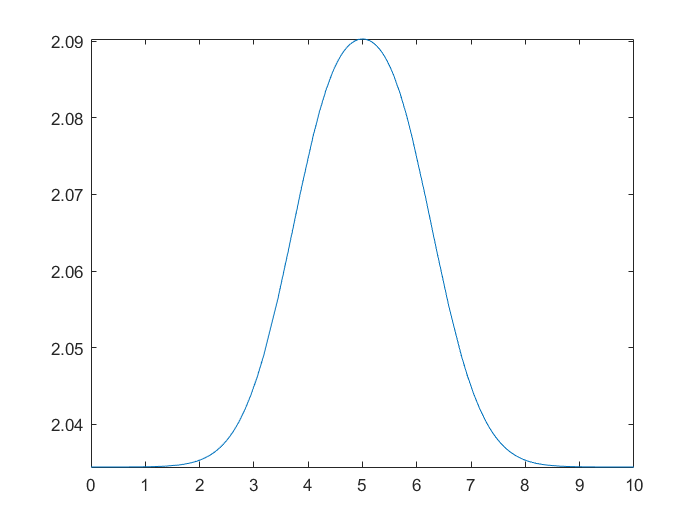

fplot(q1start.q1(1),[0,10])


qt1=q1start.q1(1)

$$qt1 = \begin{array}{l} -2\,\mathrm{atan}\left(\frac{\cos\left(\frac{2\,{\mathrm{e}}^{5\,t}\,{\mathrm{e}}^{-\frac{25}{2}}}{5\,\sqrt{{\mathrm{e}}^{t^{2}}}}\right)+\sqrt{{\sigma_{1}}^{2}-4\,\sigma_{1}+{\cos\left(\frac{2\,{\mathrm{e}}^{5\,t}\,{\mathrm{e}}^{-\frac{25}{2}}}{5\,\sqrt{{\mathrm{e}}^{t^{2}}}}\right)}^{2}+4}}{\sigma_{1}-2}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{2\,{\mathrm{e}}^{5\,t}\,{\mathrm{e}}^{-\frac{25}{2}}}{5\,\sqrt{{\mathrm{e}}^{t^{2}}}}\right) \end{array}$$

Y_ref = [qt1,qt2,qt3,diff(qt1,t),diff(qt2,t),diff(qt3,t)].'

$$Y\_ref(t) = \begin{array}{l} \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\cos\left(\sigma_{6}\right)+\sigma_{2}}{\sin\left(\sigma_{6}\right)-2}\right)\\ -\frac{\pi }{2}-\frac{2\,\sigma_{5}}{5}\\ \frac{\pi }{2}+\frac{2\,\sigma_{5}}{5}\\ \frac{2\,\left(\frac{\sin\left(\sigma_{6}\right)\,\sigma_{1}+\frac{2\,\cos\left(\sigma_{6}\right)\,\sigma_{1}}{\sigma_{2}}}{\sin\left(\sigma_{6}\right)-2}+\frac{\cos\left(\sigma_{6}\right)\,\sigma_{1}\,\left(\cos\left(\sigma_{6}\right)+\sigma_{2}\right)}{\sigma_{4}}\right)}{\frac{{\left(\cos\left(\sigma_{6}\right)+\sigma_{2}\right)}^{2}}{\sigma_{4}}+1}\\ \sigma_{3}\\ -\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sigma_{7}}{\sqrt{{\mathrm{e}}^{t^{2}}}}-\frac{2\,t\,{\mathrm{e}}^{5\,t}\,{\mathrm{e}}^{t^{2}}\,{\mathrm{e}}^{-\frac{25}{2}}}{5\,{\left({\mathrm{e}}^{t^{2}}\right)}^{3/2}}\\ \sigma_{2}=\sqrt{{\sin\left(\sigma_{6}\right)}^{2}-4\,\sin\left(\sigma_{6}\right)+{\cos\left(\sigma_{6}\right)}^{2}+4}\\ \sigma_{3}=\frac{2\,\sigma_{5}\,\left(t-5\right)}{5}\\ \sigma_{4}={\left(\sin\left(\sigma_{6}\right)-2\right)}^{2}\\ \sigma_{5}={\mathrm{e}}^{-\frac{{\left(t-5\right)}^{2}}{2}}\\ \sigma_{6}=\frac{\sigma_{7}}{5\,\sqrt{{\mathrm{e}}^{t^{2}}}}\\ \sigma_{7}=2\,{\mathrm{e}}^{5\,t}\,{\mathrm{e}}^{-\frac{25}{2}} \end{array}$$


syms T2 T3
VF = threedof_ground(T2,T3,[q(1:3);qdot(1:3)])



torque = simplify(ridgid_torque([q(1:3);qdot(1:3)]))



Atinv = jacobian(VF,[q(1:3);qdot(1:3)]);
Atinv = subs(Atinv,[T2 T3].',torque)

A(t)=subs(Atinv,[q(1:3);qdot(1:3)],Y_ref)

Btinv=jacobian(VF,[T2;T3])

$$Btinv = \begin{array}{l} \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ \frac{3\,\left(900\,\sigma_{7}+\sigma_{1}-2700\,\cos\left(q_{2}\right)-2300\right)}{\sigma_{3}} & \frac{3\,\left(\sigma_{4}-900\,\sigma_{7}-\sigma_{5}+2700\,\cos\left(q_{2}\right)\right)}{\sigma_{3}}\\ -\frac{3\,\left(1800\,\sigma_{7}+\sigma_{1}+900\,\sigma_{8}-5400\,\cos\left(q_{2}\right)-7000\right)}{\sigma_{3}} & \sigma_{2}\\ \sigma_{2} & -\frac{3\,\left(5400\,\sigma_{6}+8100\,\cos\left(2\,q_{2}\right)+900\,\sigma_{8}-11400\,\cos\left(q_{3}\right)-19000\right)}{\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=900\,\cos\left(2\,q_{3}\right)\\ \sigma_{2}=-\frac{3\,\left(\sigma_{4}-900\,\sigma_{7}-2700\,\sigma_{6}-900\,\sigma_{8}-\sigma_{5}+2700\,\cos\left(q_{2}\right)+5700\,\cos\left(q_{3}\right)+4700\right)}{\sigma_{3}}\\ \sigma_{3}=50\,\left(81\,\cos\left(2\,q_{2}\right)+45\,\cos\left(2\,q_{3}\right)-9\,\sigma_{8}-169\right)\\ \sigma_{4}=2700\,\cos\left(q_{2}-q_{3}\right)\\ \sigma_{5}=2100\,\cos\left(q_{2}+q_{3}\right)\\ \sigma_{6}=\cos\left(2\,q_{2}+q_{3}\right)\\ \sigma_{7}=\cos\left(q_{2}+2\,q_{3}\right)\\ \sigma_{8}=\cos\left(2\,q_{2}+2\,q_{3}\right) \end{array}$$

B(t)=subs(Btinv,[q(1:3);qdot(1:3)],Y_ref)

$$B(t) = \begin{array}{l} \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ \frac{3\,\left(900\,\sigma_{4}+1800\,\sigma_{3}+2300\right)}{\sigma_{2}} & \frac{3\,\left(2700\,\sigma_{4}-1800\,\sigma_{3}+2100\right)}{\sigma_{2}}\\ -\frac{3\,\left(900\,\sigma_{4}+3600\,\sigma_{3}+6100\right)}{\sigma_{2}} & \sigma_{1}\\ \sigma_{1} & -\frac{3\,\left(8100\,\sigma_{4}+6000\,\sigma_{3}+18100\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\left(4800\,\sigma_{3}-2700\,\sigma_{4}+1700\right)}{\sigma_{2}}\\ \sigma_{2}=50\,\left(126\,\sigma_{4}+178\right)\\ \sigma_{3}=\cos\left(\frac{\pi }{2}+\frac{2\,{\mathrm{e}}^{-\frac{{\left(t-5\right)}^{2}}{2}}}{5}\right)\\ \sigma_{4}=\cos\left(\frac{4\,{\mathrm{e}}^{-\frac{{\left(t-5\right)}^{2}}{2}}}{5}\right) \end{array}$$

refo = double(Y_ref(0))

refo =     2.0344
   -1.5708
    1.5708
    0.0000
   -0.0000
    0.0000


K=lqr(double(A(0)),double(B(0)),eye(6),0.01*eye(2))

K =  -105.1928  -76.6760   12.1299  -40.7782  -30.4579   -6.3279
  135.4629   89.4979  -18.6482   54.3319   25.0369   -1.9100


eig(double(A(0)-B(0)*K))

ans =  -52.2943 + 0.0000i
 -13.3934 + 0.0000i
  -2.8174 + 0.4567i
  -2.8174 - 0.4567i
  -1.0923 + 0.0000i
  -1.5669 + 0.0000i


Ao=subs(Atinv,[q(1:3);qdot(1:3)],[pi/2;0;0;0;0;0])

$$Ao = \left(\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ \frac{32373}{2600} & -\frac{8829}{325} & \frac{8829}{2600} & 0 & 0 & 0\\ -\frac{20601}{1300} & \frac{97119}{1300} & -\frac{26487}{1300} & 0 & 0 & 0\\ \frac{2943}{650} & -\frac{20601}{325} & \frac{67689}{1300} & 0 & 0 & 0 \end{array}\right)$$

Bo=subs(Btinv,[q(1:3);qdot(1:3)],[pi/2;0;0;0;0;0])

$$Bo = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ \frac{48}{13} & -\frac{36}{13}\\ -\frac{132}{13} & \frac{138}{13}\\ \frac{138}{13} & -\frac{240}{13} \end{array}\right)$$

K=lqr(double(Ao),double(Bo),eye(6),0.01*eye(2))

K =   964.7307  428.3595  114.5564  434.4013  212.2406   62.5649
  474.7306  219.9259   43.3005  213.2263  109.7202   20.8940
